clc, clear, close all
s1=20;

s2=tf(1,[1,12])

s2 =
 
    1
  ------
  s + 12
 
Continuous-time transfer function.
Model Properties


s3=tf(20,[1,0])

s3 =
 
  20
  --
  s
 
Continuous-time transfer function.
Model Properties


s4=s2*s3

s4 =
 
      20
  ----------
  s^2 + 12 s
 
Continuous-time transfer function.
Model Properties


h1=tf([0.2,0],[1])

h1 =
 
  0.2 s
 
Continuous-time transfer function.
Model Properties



CL1=feedback(s4,h1) %Feedback Loop

CL1 =
 
      20
  ----------
  s^2 + 16 s
 
Continuous-time transfer function.
Model Properties



s5=s1*CL1

s5 =
 
     400
  ----------
  s^2 + 16 s
 
Continuous-time transfer function.
Model Properties


h2=1

h2 = 1

CL2=feedback(s5,h2) %Last Feedback Loop

CL2 =
 
        400
  ----------------
  s^2 + 16 s + 400
 
Continuous-time transfer function.
Model Properties


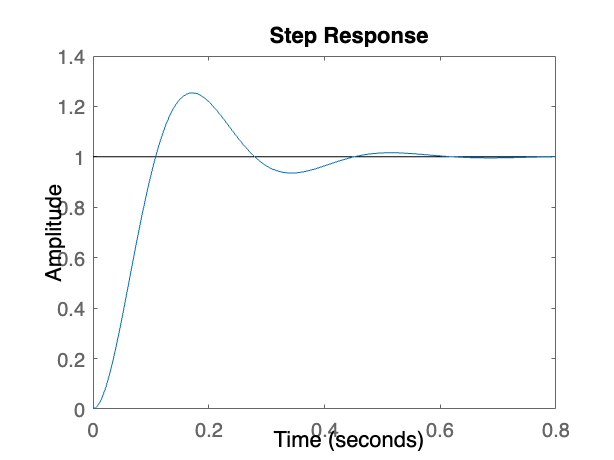

step(CL2)